Laboratório 2: geração de PN sequences usando algoritmo de gold para minimizar a função de correlação cruzada entre sinais PN distintos. - aplicação em CDMA, code division multiple access

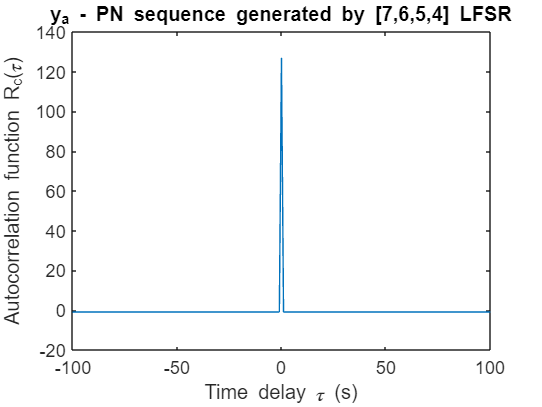

G1 = [1 1 1 1 0 0 0 1]; % first PN-sequence preferred Gold polynomial
G2 = [1 0 0 0 0 0 1 1]; % second PN-sequence preferred Gold polynomial
X0 = [1 0 0 0 0 0 0]; % initial conditions applied to FSR

y = lfsr(G1, X0);
x = lfsr(G2, X0);
N = 127;
Ryy = sequence_correlation(y, y, -100, 100);
figure(1);
plot(-100:1:100, Ryy);
xlabel('Time delay \tau (s)');
ylabel('Autocorrelation function R_c(\tau)');
title('y_a - PN sequence generated by [7,6,5,4] LFSR');

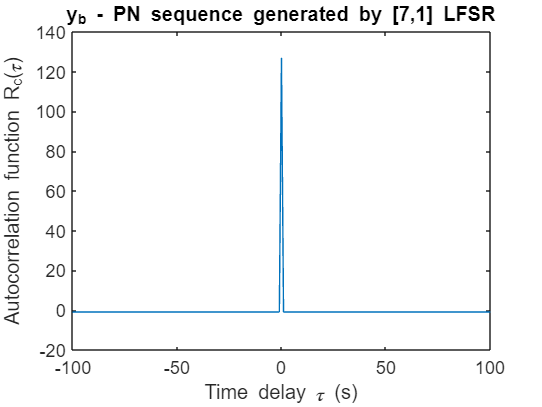


Rxx = sequence_correlation(x, x, -100, 100);
figure(2);
plot(-100:1:100, Rxx);
xlabel('Time delay \tau (s)');
ylabel('Autocorrelation function R_c(\tau)');
title('y_b - PN sequence generated by [7,1] LFSR');

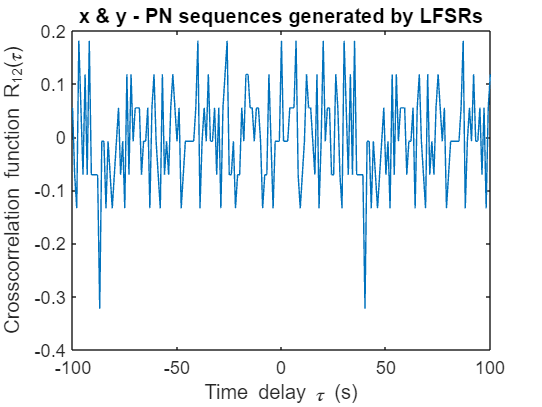


Rxy = 1/N * sequence_correlation(y, x, -100, 100);
figure(3);
plot(-100:1:100, Rxy); % not suitable for orthogonalization of users in spread spectrum systems like CDMA!
xlabel('Time delay \tau (s)');
ylabel('Crosscorrelation function R_{12}(\tau)');
title('x & y - PN sequences generated by LFSRs');

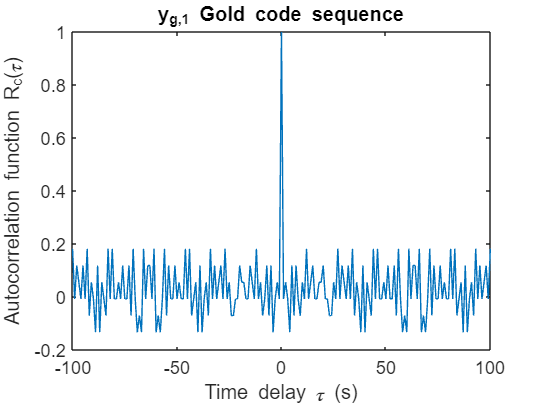


yg1 = gold_code_generator(G1,G2,X0,X0);
X1 = [0 0 0 0 0 0 1];
G3 = [1 0 0 1 0 0 0 1];
yg2 = gold_code_generator(G1,G2,X1,X0);

Rgyy = 1/N * sequence_correlation(yg1,yg1,-100,100);
figure(4);
plot(-100:1:100, Rgyy);
xlabel('Time delay \tau (s)');
ylabel('Autocorrelation function R_c(\tau)');
title('y_{g,1} Gold code sequence');

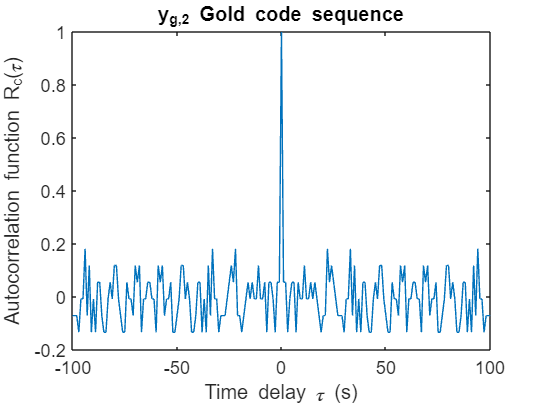


Rgyy2 = 1/N * sequence_correlation(yg2,yg2,-100,100);
figure(5);
plot(-100:1:100, Rgyy2);
xlabel('Time delay \tau (s)');
ylabel('Autocorrelation function R_c(\tau)');
title('y_{g,2} Gold code sequence');

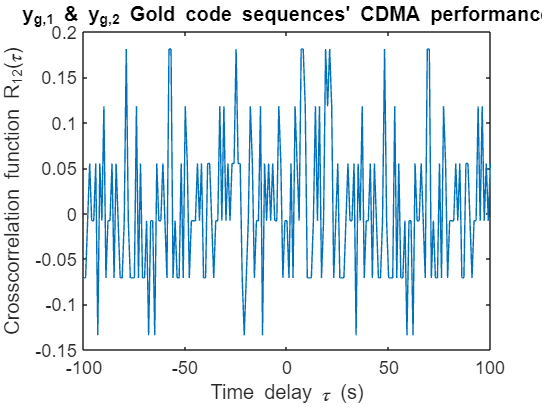


Rgy1y2 = 1/N * sequence_correlation(yg1,yg2,-100,100);
figure(6);
plot(-100:1:100, Rgy1y2);
xlabel('Time delay \tau (s)');
ylabel('Crosscorrelation function R_{12}(\tau)');
title("y_{g,1} & y_{g,2} Gold code sequences' CDMA performance");

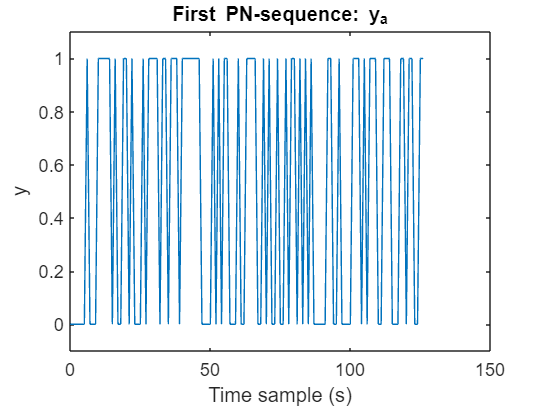


figure(7);
plot(0:1:length(y)-1, y);
xlabel('Time sample (s)');
ylabel('y')
ylim([-.1 1.1]);
title('First PN-sequence: y_a');

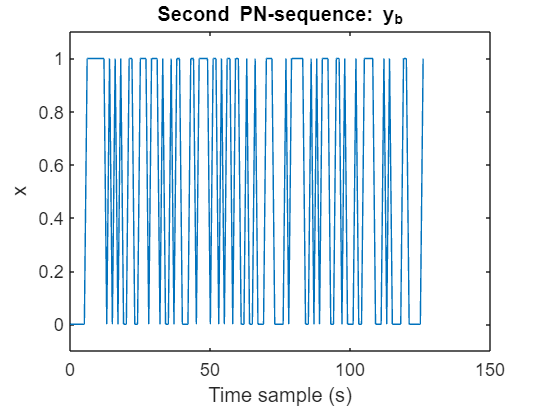


figure(8);
plot(0:1:length(x)-1, x);
xlabel('Time sample (s)');
ylabel('x')
ylim([-.1 1.1]);
title('Second PN-sequence: y_b');

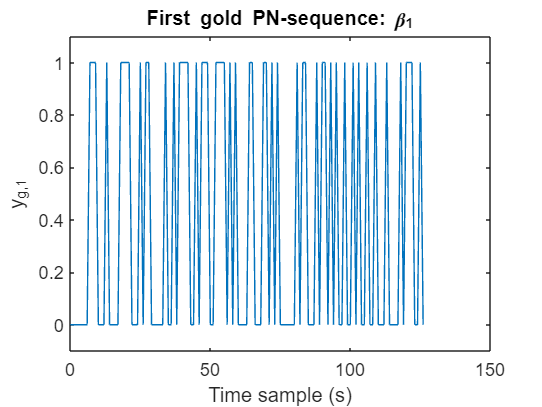


figure(9);
plot(0:1:length(yg1)-1, yg1);
xlabel('Time sample (s)');
ylabel('y_{g,1}');
ylim([-.1 1.1]);
title('First gold PN-sequence: \beta_1');

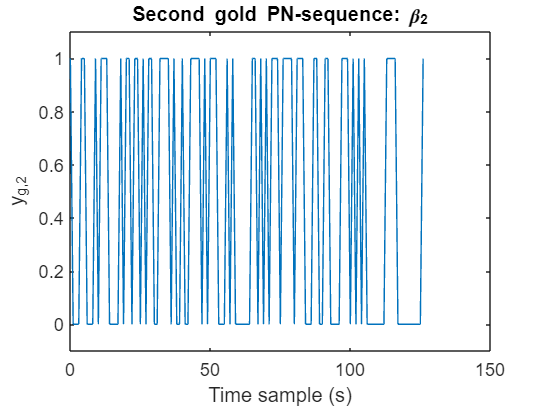


figure(9);
plot(0:1:length(yg2)-1, yg2);
xlabel('Time sample (s)');
ylabel('y_{g,2}');
ylim([-.1 1.1]);
title('Second gold PN-sequence: \beta_2');

function Rxy=sequence_correlation(x,y,k1,k2)
%Compute correlation between two binary sequences x and y
%k1 and k2 define the limits of the range of desired shifts
x=x(:);y=y(:); %serialize
if length(x) ~= length(y), error('Sequences x and y should be of same length'); end
L=length(x);
rangeOfKs = k1:1:k2; %range of cyclic shifts
Rxy=zeros(1,length(rangeOfKs));
%determine initial shift for sequence x
if k1~=0 %do not shift x if k1 is 0
start=mod(L+k1,L)+1;%+1 for matlab index
final=mod(L+k1-1,L)+1;%+1 for matlab index
x=[x(start:end);x(1:final)];%initial shifted sequence
end
q=floor(length(x)/length(y)); %assumes x is always larger
r=rem(length(x),length(y)); %remainder part
y=[repmat(y,q,1); y(1:r)];
for i=1:length(rangeOfKs)
agreements= sum(x==y);%number of agreements
disagreements = sum(x~=y); %number of disagreements
x=[x(2:end);x(1)]; %shift left once for each iteration
Rxy(i)=agreements-disagreements; %sequence correlation
end,end

function [y,states] = lfsr(G,X)
% Galois LFSR for m-sequence generation
% G - polynomial (primitive for m-sequence) arranged as vector
% X - initial state of the delay elements arranged as vector
% y - output of LFSR
% states - gives the states through which the LFSR has sequenced.
% This is particularly helpful in frequency hopping applications
% The function outputs the m-sequence for a single period
g=G(:); x=X(:); %serialize G and X as column vectors
if length(g)-length(x)~=1
error('Length of initial seed X0 should be equal to the number of delay elements (length(g)-1)');
end
% LFSR state-transition matrix construction
L = length(g)-1; % order of polynomial
A0 = [zeros(1,L-1); eye(L-1)]; % A-matrix construction
g=g(1:end-1);
A = [A0 g]; % LFSR state-transistion matrix
N = 2^L-1; % period of maximal length sequence
y = zeros(1,length(N));% array to store output
states=zeros(1,length(N));% LFSR states(useful for Frequency Hopping)
for i=1:N % repeat for each clock period
states(i)=bin2dec(char(x.'+'0'));% convert LFSR states to a number
y(i) = x(end); % output the last bit
x = mod(A*x,2); % LFSR equation
end, end

function [y] = gold_code_generator( G1,G2,X1,X2)
%Implementation of Gold code generator
%G1-preferred polynomial 1 for LFSR1 arranged as [g0 g1 g2 ... gL-1]
%G2-preferred polynomial 2 for LFSR2 arranged as [g0 g1 g2 ... gL-1]
%X1-initial seed for LFSR1 [x0 x1 x2 ... xL-1]
%X2-initial seed for LFSR2 [x0 x1 x2 ... xL-1]
%y-Gold code
%The function outputs the m-sequence for a single period
%gold_code_generator(G1,G2,X1,X2)
g1=G1(:); x1=X1(:); %serialize G1 and X1 matrices
g2=G2(:); x2=X2(:); %serialize G2 and X2 matrices
if length(g1)~=length(g2) && length(x1)~=length(x2)
error('Length mismatch between G1 & G2 or X1 & X2');
end
%LFSR state-transistion matrix construction
L = length(g1)-1; %order of polynomial
A0 = [zeros(1,L-1); eye(L-1)]; %A-matrix construction
g1=g1(1:end-1);g2=g2(1:end-1);
A1 = [A0 g1]; %LFSR1 state-transistion matrix
A2 = [A0 g2]; %LFSR2 state-transistion matrix
N = 2^L-1; %period of maximal length sequence
y = zeros(1,length(N));%array to store output
for i=1:N %repeat for each clock period
y(i)= mod(x1(end)+x2(end),2);%XOR of outputs of LFSR1 & LFSR2
x1 = mod(A1*x1,2); %LFSR equation
x2 = mod(A2*x2,2); %LFSR equation
end, end